task.location

ans = 1×1 cell array
    {'F:\OneDrive - UCLA IT Services\cs 130\dataset\dataset.zip'}


dataType = 'prediction';
mkdir (strcat(tempdir,'brainai'));
mkdir (strcat(tempdir,'brainai\\','unzip'));
mkdir (strcat(tempdir,'brainai\\','label_img'));
mkdir (strcat(tempdir,'brainai\\','data_img'));
mkdir (strcat(tempdir,'brainai\\unzip\','preview'));
unzipLocation= (strcat(tempdir,'brainai\\','unzip'));
unzip(task.location{1},unzipLocation)
images = dir(fullfile(unzipLocation,'images/','*nii*'));
images = sort({images.name});

images = 1×2 cell array
    {'sub-A00028352_ses-NFB3_T1w.nii.gz'}    {'sub-A0028352_ses-NFB3_T1w.nii.gz'}

masks = dir(fullfile(unzipLocation,'ground truth/','*nii*'));
masks = sort({masks.name});

masks = 1×2 cell array
    {'sub-A00028352_ses-NFB3_T1w_brainmask.nii.gz'}    {'sub-A0028352_ses-NFB3_T1w_brainmask.nii.gz'}

modelsDir = tempdir;

imageDir=strcat(tempdir,'brainai\\','data_img\\');

imageDir = 'C:\Users\songs\AppData\Local\Temp\brainai\\data_img\\'

labelDir=strcat(tempdir,'brainai\\','label_img\\');

labelDir = 'C:\Users\songs\AppData\Local\Temp\brainai\\label_img\\'

prefix='';

counter=1;
for i = 1:length(masks)
    disp(i);
    image_file_name = fullfile(unzipLocation,'images/',images{i});
    mask_file_name = fullfile(unzipLocation,'ground truth/',masks{i});
    image = permute(niftiread(image_file_name),[1 3 2]);
    mask = permute(niftiread(mask_file_name),[1 3 2]);
    for z = 20:165
        image_slice = image(:,:,z);
        mask_slice = mask(:,:,z);
        imwrite(uint16(image_slice),fullfile(imageDir,strcat( prefix,'img_',sprintf( '%06d', counter ),'.png')));
        imwrite(uint8(mask_slice),fullfile(labelDir,strcat(prefix, 'label_' ,sprintf( '%06d', counter ),'.png')));
        counter = counter + 1;
    end
end

     1
     2


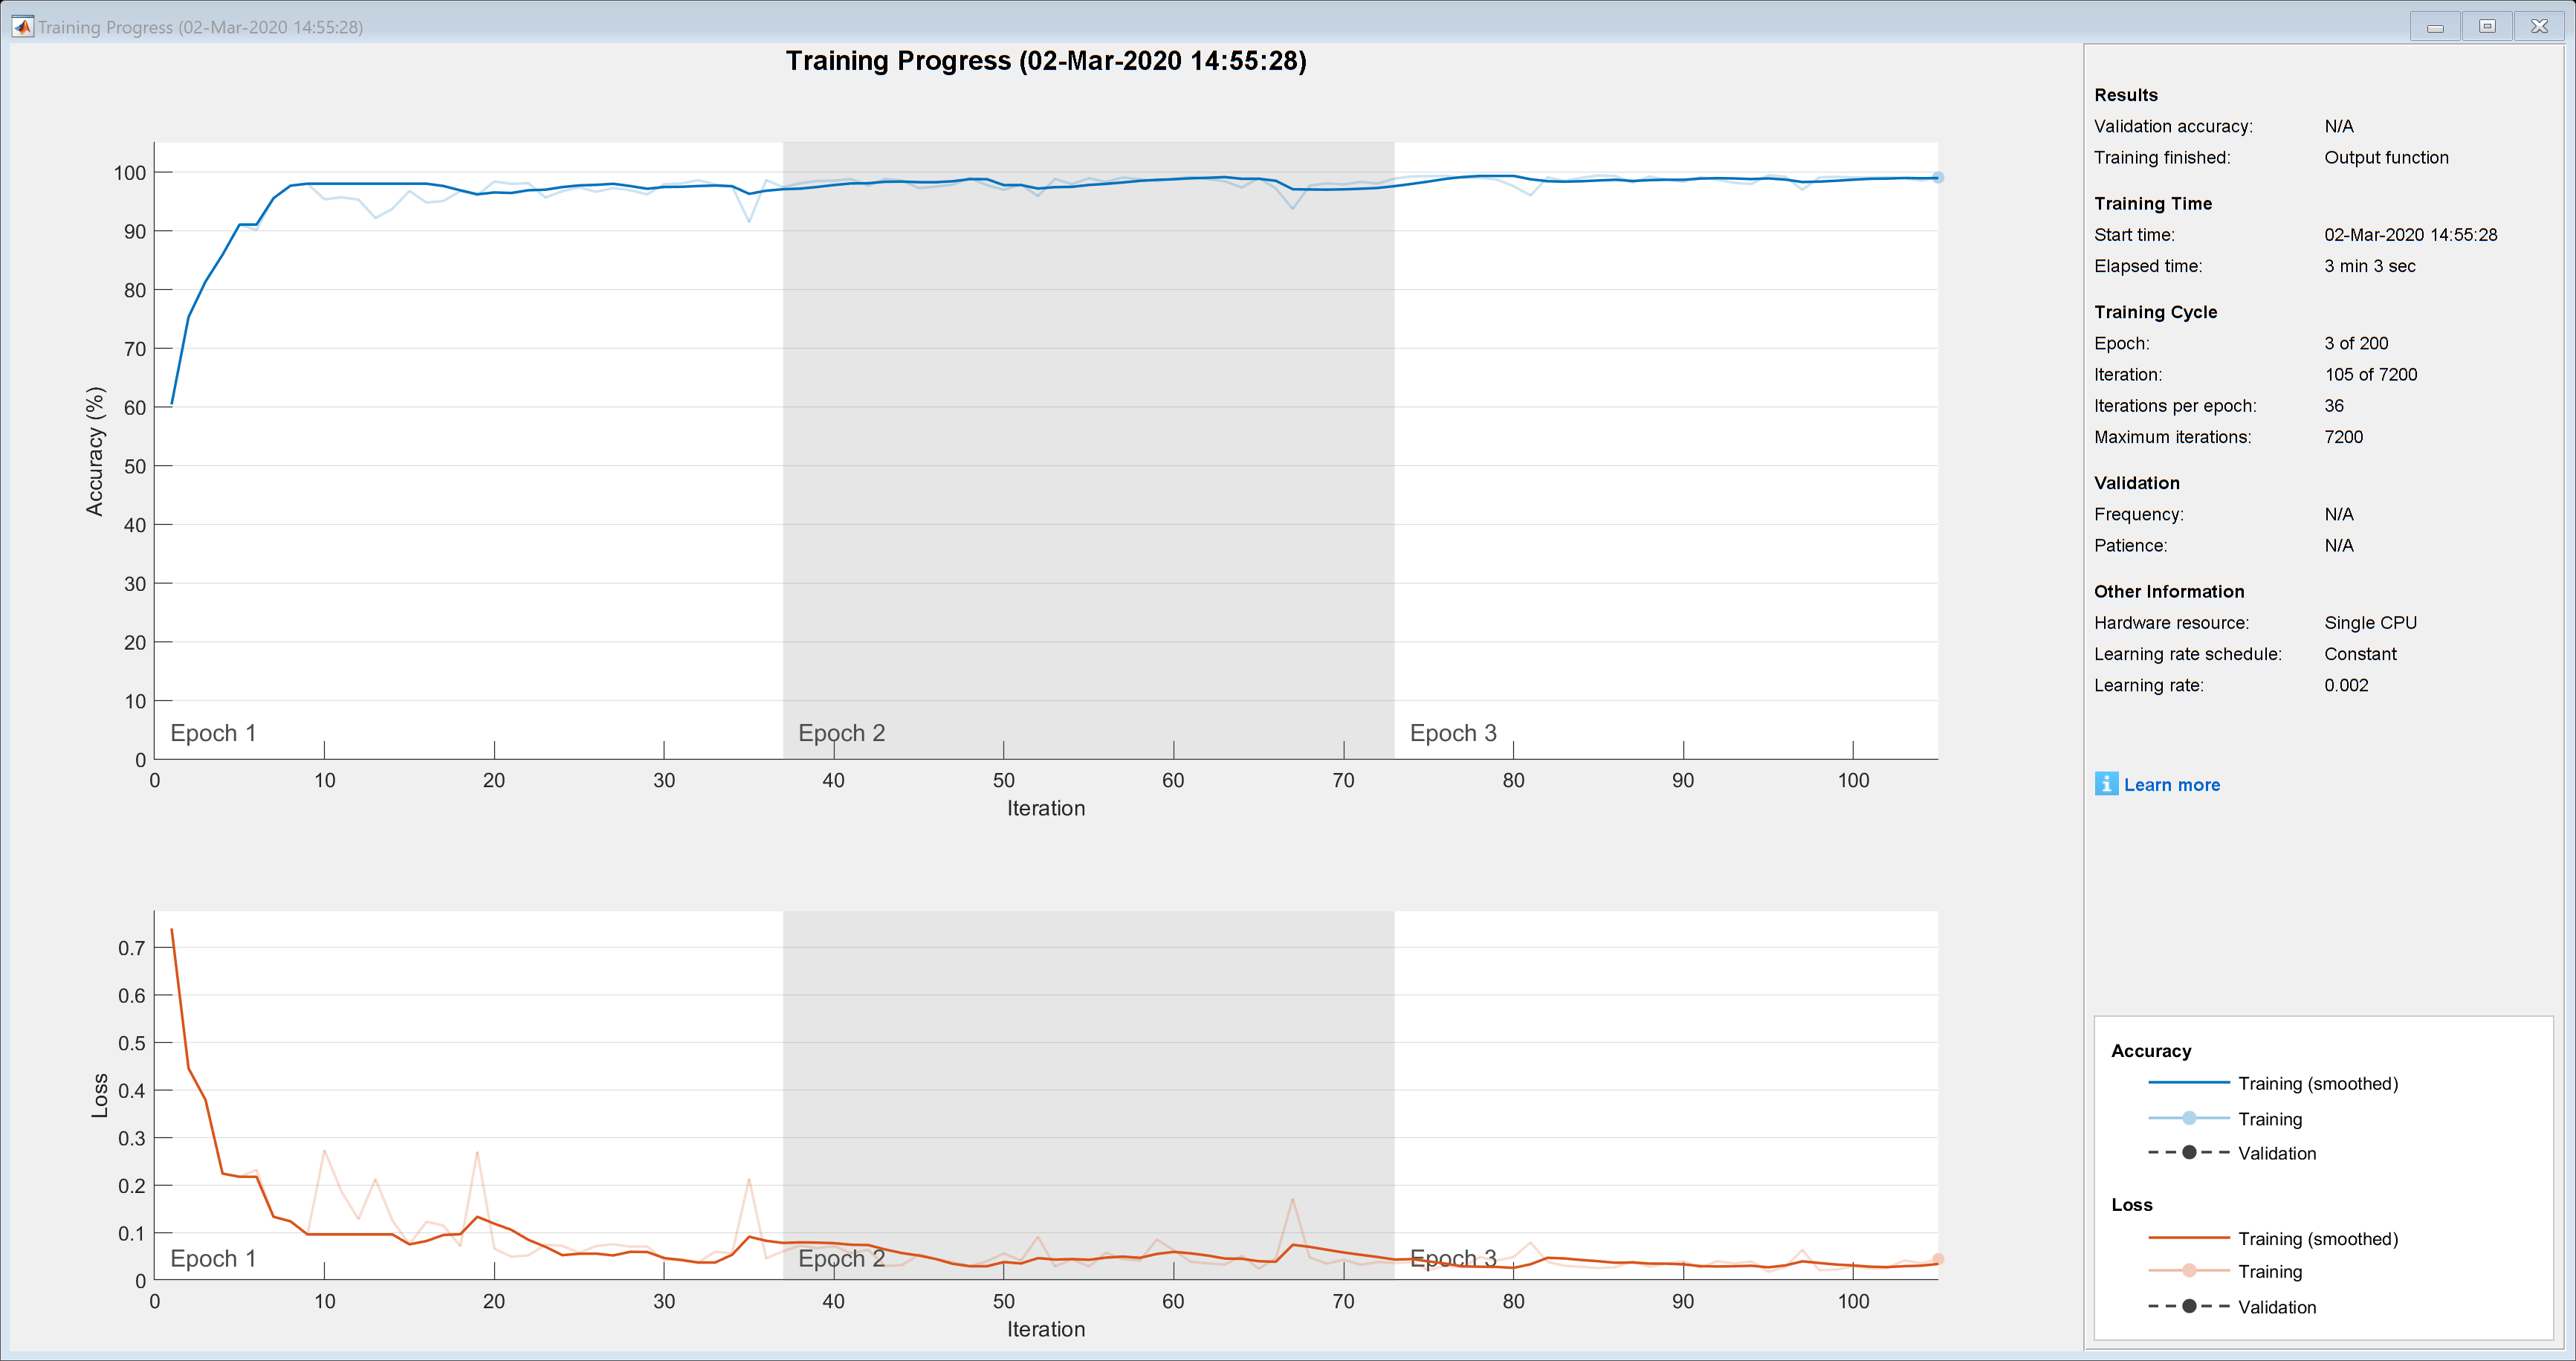

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:04 |       60.41% |       0.7395 |          0.0020 |
|       1 |          10 |       00:00:20 |       95.34% |       0.2729 |          0.0020 |
|       1 |          20 |       00:00:37 |       98.39% |       0.0660 |          0.0020 |
|       1 |          30 |       00:00:55 |       97.92% |       0.0419 |          0.0020 |
|       2 |          40 |       00:01:12 |       98.52% |       0.0712 |          0.0020 |
|       2 |          50 |       00:01:29 |       96.97% |       0.0558 |          0.0020 |
|       2 |          60 |  

imageSize = [224 224 3];
numClasses = 2;
lgraph = deeplabv3plusLayers(imageSize,numClasses,'resnet18');
lgraph = replaceLayer(lgraph,'data',[imageInputLayer(imageSize, "Name",'ImageInputLayer',"Normalization","zscore")]);
lgraph = replaceLayer(lgraph,'classification',[pixelClassificationLayer('Name','Segmentation-Layer','Classes',["brain","background"], ...
  'ClassWeights', [4.3,1])]);

imds = imageDatastore(imageDir);
classNames = ["brain","background"];
labelIDs   = [1 0];
pxds = pixelLabelDatastore(labelDir,classNames,labelIDs);
ds = pixelLabelImageDatastore(imds,pxds,"OutputSize",imageSize,'ColorPreprocessing','gray2rgb');

global metadata;
options = trainingOptions('sgdm', ...
    'InitialLearnRate',2e-3, ...
    'MaxEpochs',200, ...
    'MiniBatchSize',8,... % can be 64
    "Shuffle","every-epoch",...
    'VerboseFrequency',10, ...
    'Plots','training-progress', ...
    'OutputFcn',@(info)dbStopFunction(info,task.id,100));

net = trainNetwork(ds,lgraph,options);

metadata

metadata = struct with fields:
                 Epoch: 3
             Iteration: 105
        TimeSinceStart: 173.1689
          TrainingLoss: 0.0196
        ValidationLoss: []
         BaseLearnRate: 0.0020
      TrainingAccuracy: 99.1647
          TrainingRMSE: 24.8457
    ValidationAccuracy: []
        ValidationRMSE: []
                 State: "done"

%create model here
% copy model + update database
netFile=fullfile(modelsDir,strcat(datestr(datetime('now'),'mm_dd_yy_HH_MM_SS_FFF'),'out.mat'));
save(netFile,'net');
conn = dbconn();
query = strcat('insert into models set owner= ',int2str(task.owner),' , location= ''',netFile,''', metadata=''',jsonencode(metadata),''',name= ''unnamed_',datestr(datetime('now'),'mm/dd/HH_MM'),'''');
query

query = 'insert into models set owner=2 , location= 'C:\Users\songs\AppData\Local\Temp\03_02_20_15_33_45_774out.mat', metadata='{"Epoch":3,"Iteration":105,"TimeSinceStart":173.1688642,"TrainingLoss":0.01958022452890873,"ValidationLoss":[],"BaseLearnRate":0.0020000000949949026,"TrainingAccuracy":99.164690290178569,"TrainingRMSE":24.845735549926758,"ValidationAccuracy":[],"ValidationRMSE":[],"State":"done"}',name= 'unnamed_03/02/15_33''

execute(conn,query);
r = exec(conn,'SELECT @@IDENTITY');
r = fetch(r);
query = strcat('update tasks set model =',int2str(r.Data{1}),' where id =',int2str(task.id));
exec(conn,query);
close(conn);    


%cleanup
rmdir(strcat(tempdir,'brainai'), 's')